# Working with automated computations: Imported and Computed tables

Welcome back! In this session, we are going to continue working with the pipeline for the mouse electrophysiology example. 

In this session, we will learn to:

- import neuron activity data from data files into an `Imported` table

- compute various statistics for each neuron by defining a `Computed` table

- define a `Lookup` table to store parameters for computation

- define another `Computed` table to perform spike detection and store the detected spikes

- automatically trigger computations for all missing entries with `populate`

Now we would like to continue working with the tables we defined in the previous session. To do so, we would need the classes for each table: `Mouse` and `Session`. We can either redefine it here, but for your convenience, we have included the schema and table class definitions in a package called +`session2`, from which you can import the classes. We will use the schema again to define more tables. When creating the schema, the database should be named as `username_session2.`

create_session2

This script also fills each table with data to make sure we are all on the same page.

# Importing data from data files

Recall from the project description

- In each experimental session, you record electrical activity from a single neuron. You use recording equipment that produces separate data files for each neuron you recorded.

Our recording equipment produces a data file for each neuron recorded. Since we record from one neuron per session, there should be one data file for each session.

In the `data` directory, you will find `.mat` files with names like `data_100_2018-05-25.mat`.

As you might have guessed, these are the data for the recording sessions in the `Session` table, and each file are named according to the `mouse_id` and `session_date` - the attributes of the primary keys - in the format `data_{mouse_id}_{session_date}.mat`.

So `data_100_2018-05-25.mat` is the data for session identified by `mouse_id = 100` and `session_date = "2018-05-25"`.

## Looking at the data

Let's take a quick peek at the data file content.

First, let's pick a session to load the data for. To do this we are going to first fetch all the **primary key attributes** of `Session` as a structure array. We make use of the  `fetch` to achieve this.

keys = fetch(session2.Session)

Any item in this array of keys can be used to uniquely identify a single session!

% Enter your code here


Let's take the first key, and generate the file name that corresponds to this session. Remember the `data_{mouse_id}_{session_date}.mat` filename convetion!

key = keys(1);
filename = sprintf('data/data_%d_%s.mat', key.mouse_id, key.session_date)

Let's take a look at its contents

loaded_data = load(filename);
data = loaded_data.data

And check the size of the data

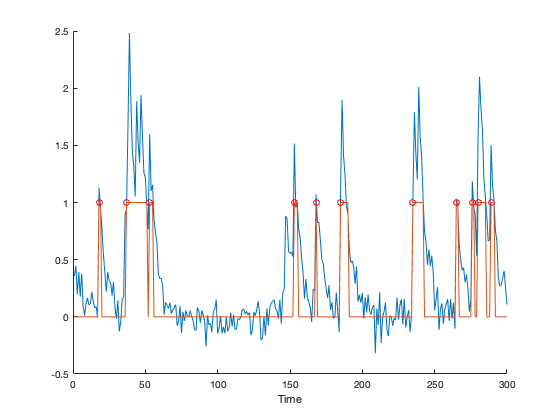

size(data)

This vector represents a (simulated) recording of raw arbituary electric activity from a single neuron over 1000 time bins.

figure; plot(data)

## Defining the table for recorded neurons

We now would like to have all these recorded `Neuron` represented and stored in our data pipeline.

Since we only record a single neuron from each session, a `Neuron` can be uniquely identified by knowing the `Session` it was recorded in. For each `Neuron`, we want to store the neural **activity** found in the data file.

dj.new

Let's declare this table:

session2.Neuron

Let's check the status of our data pipeline.

erd session2

We defined `activity` as a `longblob` so that it can store a vector holding the electric activity over time. This vector will be imported from the file corresponding to each neuron.

Note that our `Neuron` class inherits from `dj.Imported` instaed of `dj.Manual` like others. This is because **this table's content will depend on data imported from an external file**. The `Manual` vs `Imported` are said to specify the **tier of the table**.

## DataJoint table tiers

In DataJoint, the tier of the table indicates **the nature of the data and the data source for the table**. So far we have encountered two table tiers: `Manual` and `Imported`, and we will encounter the two other major tiers in this session. 

DataJoint tables in `Manual` tier, or simply **Manual tables** indicate that its contents are **manually** entered by either experimenters or a recording system, and its content **do not depend on external data files or other tables**. This is the most basic table type you will encounter, especially as the tables at the beggining of the pipeline. In the ERD, `Manual` tables are depicted by green squares.

On the other hand, **Imported tables** are understood to pull data (or *import* data) from external data files, and come equipped with functionalities to perform this importing process automatically, as we will see shortly! In the ERD, `Imported` tables are depicted by blue ellipses.

## Importing data into the `Imported` table

Rather than filling out the content of the table manually using the `insert` methods, we are going to make use of the `makeTuples` and `populate` logic that comes with `Imported` tables to automatically figure out what needs to be imported and perform the import!

## `makeTuples` and `populate` methods

Let us keep the `makeTuples` function empty and try to call the function.

% call the `populate` function

When you call `populate` on an `Imported` table, this triggers DataJoint to look up all tables that the `Imported` table depends on.

For **every unique combination of entries in the depended or "parent" tables**, DataJoint calls `makeTuples` function, passing in the primary key of the parent(s).

Because `Neuron` depends on `Session`, `Neuron`'s `makeTuples` method was called for each entry of `Session`

session2.Session

Note that `makeTuples` only receives the *primary key attributes* of `Session` (`mouse_id` and `session_date`) but not the other attributes.

## Implementing `makeTuples`

Now we have a better understanding of `makeTuple`, let's implement `makeTuples` to perform the importing of data from file.

edit session2.Neuron

Notice that we added the missing attribute information `activity` into the `key` struct, and finally **inserted the entry** into `self` = `Neuron` table. The `makeTuples` method's job is to create and insert a new entry corresponding to the `key` into this table!

Finally, let's go ahead and call `populate` to actually populate the `Neuron` table, filling it with data loaded from data files!

% Call `populate` method again
populate(session2.Neuron)

Check the `Neuron` table now!

session2.Neuron

What will happen if we call the `populate` again?

populate(session2.Neuron)

That's right - nothing! This makes sense, because we have imported `Neuron` for all entries in `Session` and nothing is left to be imported.

Now what happens if we insert a new entry into `Session`?

insert(session2.Session, {100 "2018-06-01" 1 "Jacob Reimer"})

We can find all `Session` without corresponding `Neuron` entry with the** negative restriction operator** `-`

% select all Session entries *without* a corresponding entry in Neuron


populate(session2.Neuron)

session2.Neuron

# Computations in data pipeline

Now we have successfully imported all data we have into our pipeline, it's time for us to start analyzing them! 

When you perform computations in the DataJoint data pipeline, you focus and design tables in terms of **what** is it that you are computing rather than the **how**. You should think in terms of the "things" that you are computing!

Now, let's say that we want to compute the satististics, such as mean, standard deviation, and maximum value of each of our neuron's activity traces. Hence we want to compute the neuron's **activity statistics** for each neuron!

So the new "thing" or entity here is `ActivityStatistics`, where each entry corresponds to the statistics of a single `Neuron`. Let's start designing the table, paying special attention to the dependencies.

**Statistics of neuron activities**

Before we create the table to store the statistics, let's think about how we might go about computing interesting statistics for a single neuron.

Let's start by fetching one neuron to work with.

keys = fetch(session2.Neuron);

% pick one key
key = keys(1)

session2.Neuron & key

Let's then grab the `activity` data as a vector. As discussed in the last session, we can fetch it!

activity = fetch1(session2.Neuron & key, 'activity')

Now we can compute some statistics.

% mean activity


% standard deviation of the activity


% maximum of the activity


This gives us a good idea on how to:

1. fetch the activity of a neuron knowing its primary key, and

2. compute interesting statistics

Armed with this knowledge, let's go ahead and define the table for 

with primary keys:

- primary keys in table Neuron

and additional attributes:

- mean

- stdev

- max

**Defining **`ActivityStatistics`** table**

Let's go ahead and work out the definition of the table.

dj.new

Let's go ahead to populate the table.

populate(session2.ActivityStatistics)

session2.ActivityStatistics

Now you have computed the activity statistics for each neuron!

# Spike detection

Now, let's go ahead and tackle a more challenging computation. While having raw neural traces in itself can be quite interesting, nothing is as exciting as spikes! Let's take a look at the neurons activities and plot them.

% get all keys


% fetch all activities - returned as a cell array


figure; 
for i = 1:length(activities)
    subplot(length(activities),1, i)
    activity = activities(i);
    plot(activity{:})
    xlabel('Time')
    ylabel('Activity')
end

Now let's focus on one trace instead.

figure;
activity = fetch1(session2.Neuron & keys(1), 'activity');
plot(activity); xlabel('Time'); ylabel('Activity'); xlim([0, 300])

Perhaps we can use threshold to detect when a spike occurs.Threshold of 0.5 might be a good start.

threshold = 0.5;

% find activity above threshold
above_thrs = activity > threshold;   

figure; hold on
plot(activity)
plot(above_thrs)
xlabel('Time')
xlim([0, 300])

We want to find out **when** it crossed the threshold. That is, find time bins where `above_thrs` goes from 0 (`False`) to 1 (`True`).

rising = diff(above_thrs) > 0;  % find rising edge of crossing threshold
spikes = [0, rising];   % prepend 0 to account for shortening due to diff

figure; hold on
plot(activity)
plot(above_thrs)
plot(find(spikes>0), 1,  'ro'); % plot only spike points
xlabel('Time')
xlim([0, 300])

Finally, let's also compute the spike counts.

count = sum(spikes)

Here is our complete spike detection algorithm:

% Enter your code here - try different values of threshold!
%threshold = 

% find activity above threshold
above_thrs = activity > threshold;
rising = diff(above_thrs) > 0;  % find rising edge of crossing threshold
spikes = [0, rising];   % prepend 0 to account for shortening due to diff
count = sum(spikes)    % compute totoal spk counts

figure; hold on
plot(activity)
plot(above_thrs)
plot(find(spikes>0), 1,  'ro'); % plot only spike points
xlabel('Time')
xlim([0, 300])

 Now notice that the exact spikes you detect depend on the value of the `threshold`. Therefore, the `threshold` is a parameter for our spike detection computation. Rather than fixing the value of the threshold, we might want to try different values and see what works well.

In other words, you want to compute `Spikes` for a **combination** of `Neuron`'s and different `threshold` values. To do this while still taking advantage of the `makeTuples` and `populate` logic, you would want to define a table to house parameters for spike detection in a `Lookup` table!

## Parameter `Lookup` table

Let's define `SpikeDetectionParam` table to hold different parameter configuration for our spike detection algorithm. We are going to define this table as a `Lookup` table, rather than a `Manual` table. By now, you know that `Lookup` must be yet another **table tier** in DataJoint. `Lookup` tables are depicted by a **gray star** in the ERD.

This tier indicates that the table will contain information:

- that will be referenced by other tables

- that doesn't change much - usually contains a few pre-known entries

dj.new

session2.SpikeDetectionParam

figure; erd session2

**Defining **`Spikes`** table**

dj.new

The implementation of the spike detection is pretty much what we had above, except that we now fetch the value of `threshold` from the `SpikeDetectionParam` table.

Looking at the `Spikes` table, we see that it indeed inherits the primary key attributes from **both Neuron (`mouse_id`, `session_date`) and SpikeDetectionParam (`sdp_id`)**

session2.Spikes

**Populating **`Spikes`** table**

We are now ready to populate! When we call `populate` on `Spikes`, DataJoint will automatically call `make` on **every valid combination of the parent tables - Neuron and SpikeDetectionParam**.

% Enter your code, populate the Spike table


Why there is nothing to populate? Looking at `SpikeDetectionParam` reveals the issue:

session2.SpikeDetectionParam

That's right! We have not added a detection parameter set yet. Let's go ahead and add one.

insert(session2.SpikeDetectionParam, {0, 0.5})
session2.SpikeDetectionParam

% populate the Spike table for real!
populate(session2.Spikes)

Check the table

session2.Spikes

**Trying out other parameter values**

insert(session2.SpikeDetectionParam, {1, 0.9})
session2.SpikeDetectionParam

Let's see how different thresholds affect the results.

populate(session2.Spikes)

session2.Spikes

You can see that the results of spike detection under different parameter settings can live happily next to each other, without any confusion as to what is what.

Let's insert a couple more entries into `SpikeDetectionParam` 

insert(session2.SpikeDetectionParam, {
2, 0.8
3, 0.6
4, 0.3
})

session2.SpikeDetectionParam

What if I only want to populate with `sdp_id=3`?

There are two approaches. 

First approach, restrict when calling the `populate` method

% Enter your code here, restrict the populate


Second approach, restrict in the class `session2.Spikes` with a property called `popRel`

edit session2.Spikes

populate(session2.Spikes)

The first approach is applicable to quickly populating a sebset of the entries, while the second is suitable for more systematic restrictions.

## Deleting entries "upstream"

Now let's say that we decided that we don't like the first spike threshold of `0.5`. While there is really nothing wrong keeping those results around, you might decide that you'd rather delete all computations performed with that threshold to keep your tables clean.

While you can restrict `Spikes` table to the specific parameter id (i.e. `sdp_id = 0`) and delete the entries:

% Enter your code here to delete all entries with sdp_id = 0


We can also simply delete the unwanted paramter from the `SpikeDetectionParam` table, and let DataJoint cascade the deletion:

del(session2.SpikeDetectionParam  & 'sdp_id = 0')

session2.Spikes

# Summary

Congratulations! You have successfully extended your pipeline with a table to represent recorded data (`Neuron` as `Imported` table), tables that performs and represents computation results (`ActivityStatistics` and `Spikes` as `Computed` tables) and a table to hold computation parameters (`SpikeDetectionParam` as `Lookup` table).

erd session2

Our pipeline is still fairly simple but completely capable of handling analysis!

In the next session, we are going to revisit some of the **common design patterns** that were used when designing our pipeline. We will also tackle some more query challenges to horn in our DataJoint querying skills.